%% 16-QAM Transceiver with NI USRP-2900 (No qammod / qamdemod)
clear; clc; close all;

%% 1. System Parameters
centerFreq   = 915e6;          % 915 MHz ISM band
sampleRate   = 1e6;            % 1 Msps baseband rate
txGain       = 40;             % dB
rxGain       = 10;             % dB
usrpIP       = '310738C'; % USRP Serial / IP Address

M            = 16;
k            = log2(M);        % 4 bits per symbol
numSymbols   = 2000;
sps          = 4;              % Samples per symbol

%% 2. Custom 16-QAM Modulation
txBits = randi([0 1], numSymbols * k, 1);

% Custom QAM Modulation (Replaces qammod)
txSymbols = custom_qammod_16(txBits);

% Root Raised Cosine (RRC) Transmit Filter
rolloff = 0.35;
filterSpanInSymbols = 8;
rrcFilter = rcosdesign(rolloff, filterSpanInSymbols, sps, 'sqrt');

% Pulse Shaping
txWaveform = upfirdn(txSymbols, rrcFilter, sps);

%% 3. USRP Radio Setup
try
    txRadio = comm.SDRuTransmitter(...
        'Platform',             'B200', ...
        'SerialNum',            usrpIP, ...
        'CenterFrequency',      centerFreq, ...
        'Gain',                 txGain, ...
        'MasterClockRate',      32e6, ...
        'InterpolationFactor',  32e6 / sampleRate);

    rxRadio = comm.SDRuReceiver(...
        'Platform',             'B200', ...
        'SerialNum',            usrpIP, ...
        'CenterFrequency',      centerFreq, ...
        'Gain',                 rxGain, ...
        'MasterClockRate',      32e6, ...
        'DecimationFactor',     32e6 / sampleRate, ...
        'OutputDataType',       'double', ...
        'SamplesPerFrame',      length(txWaveform) * 2);
catch ME
    error('Failed to connect to USRP 2900: %s', ME.message);
end

%% 4. Transmit and Receive
disp('Transmitting and receiving over USRP 2900...');

Transmitting and receiving over USRP 2900...



for i = 1:100
    txRadio(txWaveform);
end

[rxWaveform, len, overflow] = rxRadio();

release(txRadio);
release(rxRadio);

%% 5. Receiver Processing & Custom Demodulation
% Matched Filtering
rxFiltered = upfirdn(rxWaveform, rrcFilter, 1, sps);

% Delay Compensation
filterDelay = filterSpanInSymbols;
rxSignal = rxFiltered(filterDelay + 1 : end - filterDelay);

% Downsample and normalize power
rxSymbols = rxSignal(1 : sps : end); 
rxSymbols = rxSymbols / sqrt(mean(abs(rxSymbols).^2));

% Custom QAM Demodulation (Replaces qamdemod)
rxBits = custom_qamdemod_16(rxSymbols);

%% 6. Bit Error Rate (BER) & Visualization
minLen = min(length(txBits), length(rxBits));
[numErrors, ber] = biterr(txBits(1:minLen), rxBits(1:minLen));

fprintf('\n--- Performance Summary ---\n');


--- Performance Summary ---


fprintf('Bits Transmitted : %d\n', length(txBits));

Bits Transmitted : 8000


fprintf('Bit Errors       : %d\n', numErrors);

Bit Errors       : 2050


fprintf('Bit Error Rate   : %.4f\n', ber);

Bit Error Rate   : 0.5115


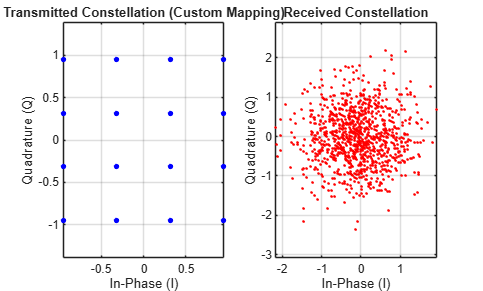


% Plot Constellations
figure('Name', 'Custom 16-QAM Transceiver', 'NumberTitle', 'off');

subplot(1,2,1);
plot(real(txSymbols), imag(txSymbols), 'b.', 'MarkerSize', 12);
grid on; axis equal;
title('Transmitted Constellation (Custom Mapping)');
xlabel('In-Phase (I)'); ylabel('Quadrature (Q)');

subplot(1,2,2);
plot(real(rxSymbols(1:min(length(rxSymbols), numSymbols))), imag(rxSymbols(1:min(length(rxSymbols), numSymbols))), 'r.');
grid on; axis equal;
title('Received Constellation');
xlabel('In-Phase (I)'); ylabel('Quadrature (Q)');


%% --- Custom Functions ---
function symbols = custom_qammod_16(bits)
    bitsMatrix = reshape(bits, 4, []).';
    I_bits = bitsMatrix(:, 1:2);
    Q_bits = bitsMatrix(:, 3:4);
    
    I = map_bits_to_pam4(I_bits);
    Q = map_bits_to_pam4(Q_bits);
    
    symbols = (I + 1i * Q) / sqrt(10);
end

function pam4 = map_bits_to_pam4(bit_pairs)
    idx = bit_pairs(:,1)*2 + bit_pairs(:,2);
    pam_table = [-3; -1; 3; 1]; % Gray Code: 00->-3, 01->-1, 10->3, 11->1
    pam4 = pam_table(idx + 1);
end

function bits = custom_qamdemod_16(symbols)
    raw_symbols = symbols * sqrt(10);
    I = real(raw_symbols);
    Q = imag(raw_symbols);
    
    I_bits = map_pam4_to_bits(I);
    Q_bits = map_pam4_to_bits(Q);
    
    bitsMatrix = [I_bits, Q_bits];
    bits = reshape(bitsMatrix.', [], 1);
end

function bit_pairs = map_pam4_to_bits(val)
    n = length(val);
    bit_pairs = zeros(n, 2);
    for i = 1:n
        if val(i) < -2
            bit_pairs(i, :) = [0, 0];
        elseif val(i) < 0
            bit_pairs(i, :) = [0, 1];
        elseif val(i) < 2
            bit_pairs(i, :) = [1, 1];
        else
            bit_pairs(i, :) = [1, 0];
        end
    end
end